% get eigenface and originalmean from the csv file we save
eigenface=csvread("eigenface.csv");
origmean=csvread("original_mean.csv");
origmean=repmat(origmean,1,100);

% get 1 random photo from each person -> total 100 photos
selectfolderpath="selected_test_images/";

if ~isfolder(selectfolderpath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',selectfolderpath);
    uiwait(warndlg(errorMessage));
    return;
end

selectpattern=fullfile(selectfolderpath,'*.bmp');
selectimg=dir(selectpattern);
numofselect=length(selectimg)

numofselect = 100

if numofselect~=0
    for i=1:numofselect
        fname=fullfile(selectfolderpath,selectimg(i).name);
        delete(fname);
    end
end

testdatapath="/home/dmplus/2019_juniorI/CV/assignment/assignment1/dataset/AR/AR_Test_image"

testdatapath = "/home/dmplus/2019_juniorI/CV/assignment/assignment1/dataset/AR/AR_Test_image"

if ~isfolder(testdatapath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',testdatapath);
    uiwait(warndlg(errorMessage));
    return;
end

testpattern=fullfile(testdatapath,'*.bmp');
testimgs=dir(testpattern);
randnumvec=zeros(13,1);

for i=1:100
    randnumvec(i)=randsample(13,1);
end

for i=1:100
    idx=13*(i-1);
    idx=idx+randnumvec(i);
    curfname=fullfile(testdatapath,testimgs(idx).name);
    img=imread(curfname);
    fname=testimgs(idx).name;
    disp(fname);
    imwrite(img,fullfile('selected_test_images/',testimgs(idx).name));
end

m-001-19.bmp
m-002-21.bmp
m-003-23.bmp
m-004-22.bmp
m-005-14.bmp
m-006-20.bmp
m-007-19.bmp
m-008-23.bmp
m-009-20.bmp
m-010-15.bmp
m-011-24.bmp
m-012-15.bmp
m-013-15.bmp
m-014-19.bmp
m-015-19.bmp
m-016-20.bmp
m-017-22.bmp
m-018-17.bmp
m-019-17.bmp
m-020-23.bmp
m-021-17.bmp
m-022-22.bmp
m-023-18.bmp
m-024-22.bmp
m-025-21.bmp
m-026-25.bmp
m-027-20.bmp
m-028-19.bmp
m-029-18.bmp
m-030-20.bmp
m-031-16.bmp
m-032-20.bmp
m-033-18.bmp
m-034-16.bmp
m-035-17.bmp
m-036-17.bmp
m-037-16.bmp
m-038-15.bmp
m-039-22.bmp
m-040-19.bmp
m-041-22.bmp
m-042-22.bmp
m-043-16.bmp
m-044-17.bmp
m-045-21.bmp
m-046-19.bmp
m-047-24.bmp
m-048-22.bmp
m-049-24.bmp
m-050-17.bmp
w-0100-21.bmp
w-051-25.bmp
w-052-18.bmp
w-053-26.bmp
w-054-20.bmp
w-055-21.bmp
w-056-21.bmp
w-057-20.bmp
w-058-16.bmp
w-059-15.bmp
w-060-19.bmp
w-061-18.bmp
w-062-22.bmp
w-063-26.bmp
w-064-16.bmp
w-065-23.bmp
w-066-20.bmp
w-067-25.bmp
w-068-19.bmp
w-069-23.bmp
w-070-18.bmp
w-071-21.bmp
w-072-14.bmp
w-073-17.bmp
w-074-22.bmp
w-075-23.bmp
w-076-22.bm

% preprocess the selected test images
% 1. grayscale 2. matrix -> vector 3. 100 vector concatenate to into 1
% matrix
selectfolderpath="selected_test_images/";

if ~isfolder(selectfolderpath)
    errorMessage=sprintf('Error: The following folder does not exist:\n%s',selectfolderpath);
    uiwait(warndlg(errorMessage));
    return;
end

selectpattern=fullfile(selectfolderpath,'*.bmp');
selectimg=dir(selectpattern);
numofselect=length(selectimg);

imgmat=zeros(19800,100);

for i=1:100
    fname=fullfile(selectfolderpath,selectimg(i).name);
    finfo=imread(fname);
    grayimg=rgb2gray(finfo);
    grayimg=im2double(grayimg);
    vec=grayimg(:);
    imgmat(:,i)=vec;
end

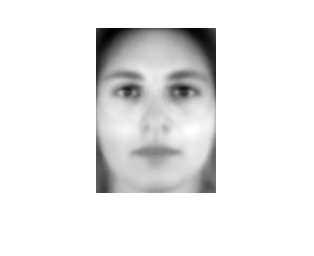

% compress and decompress the image when d=1,5,9
reducedimdir="after_reduce_dimension/";

% d=1
d1path=strcat(reducedimdir,"d1/");
projectimg=imgmat'*eigenface(:,1);
origimg=projectimg*eigenface(:,1)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    %imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d1path,strcat(fname,'.bmp')));
end

% d=5
d5path=strcat(reducedimdir,"d5/");
projectimg=imgmat'*eigenface(:,1:5);
origimg=projectimg*eigenface(:,1:5)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    %imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d5path,strcat(fname,'.bmp')));
end

% d=9
d9path=strcat(reducedimdir,"d9/");
projectimg=imgmat'*eigenface(:,1:9);
origimg=projectimg*eigenface(:,1:9)';
origimg=origimg'+origmean;
vec=num2cell(origimg,1);
for i=1:100
    mat=reshape(vec{i},165,120);
    gray=mat2gray(mat);
    imshow(gray);
    fname=strcat('person',num2str(i));
    imwrite(gray,fullfile(d9path,strcat(fname,'.bmp')));
end